# Analysis of Electricity Usage

The spreadsheet `electricity.xlsx` contains a monthly record of total electricity usage in the United States, from January 1990 to December 2019, divided by sector (residential, commercial, industrial, and total, which includes other miscellaneous sectors). The values represent the total consumption for the given month, in units of megawatt hours.

Data from US Energy Information Administration (EIA): [http://www.eia.gov/electricity/data.cfm](http://www.eia.gov/electricity/data.cfm)

## Load data 

Load the electricity usage data.

data = readtable("electricity.xlsx");

Extract the usage data into a matrix.

sectors = data.Properties.VariableNames(2:end);
usage = data{:,sectors};
dates = data.Date;

## Normalize the data

Normalize monthly total usage to average daily usage.

Find the number of days in each month of the `dates` vector.

nextmonth = dates(end) + calmonths(1);
datesplus1 = [dates;nextmonth];
daysPerMth = days(diff(datesplus1));

Calculate average daily usage.

usage = usage./daysPerMth;

## Fill in missing data

Interpolate missing electricity data using a cubic spline and the dates as the sample points.

usage = fillmissing(usage,"spline","SamplePoints",dates);

## Smooth the data.

The usage fluctuates over the course of a year. Smooth the data to remove small-scale noise using a 24-month moving average.

% Smooth input data
usageMovAvg = smoothdata(usage,'movmean',24);

Plot the results.

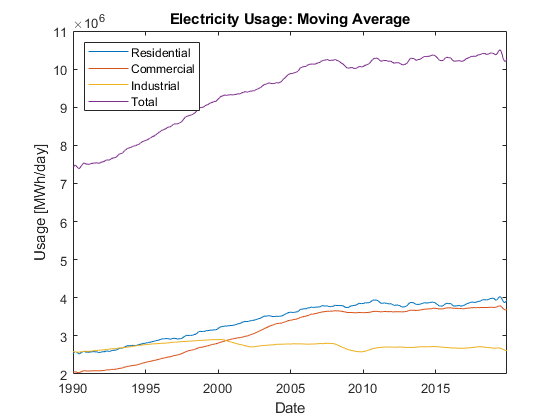

plot(dates,usageMovAvg)
title("Electricity Usage: Moving Average")
xlabel("Date")
ylabel("Usage [MWh/day]")
legend(sectors,"Location","northwest")

## Fit trend model to residential data

Find a cubic polynomial fit to the electricity data.

resUsage = usage(:,1);
elapsedYears = years(dates - dates(1));
c = polyfit(elapsedYears,resUsage,3);

Project the model into 2021 and plot.

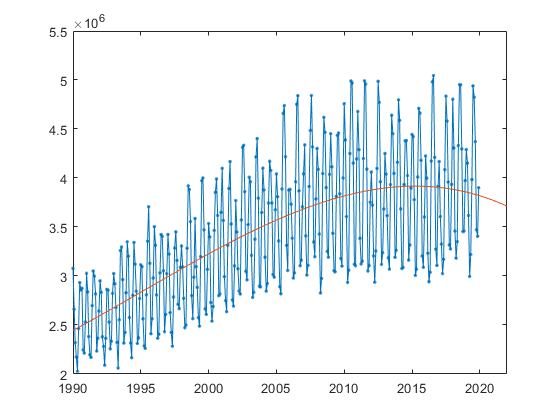

elYrFit = linspace(0,32,501);
resUsageFit = polyval(c,elYrFit);
plot(dates,resUsage,".-")
hold on
datesFit = dates(1) + years(elYrFit);
plot(datesFit,resUsageFit)
hold off

## Plot the data, smoothed data, and model together

Plot the usage data with customized markers.

plot(dates,resUsage,"o-","MarkerSize",4,"MarkerFaceColor",[0.5 0.5 1])

Add the moving average with a green line.

hold on
plot(dates,usageMovAvg(:,1),"Color",[0 .5 0],"LineWidth",2)

Add the model with a thick red line, and labels to the plot.

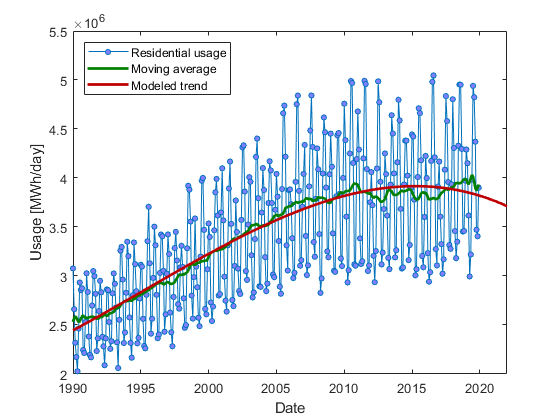

plot(datesFit,resUsageFit,"Color",[0.75 0 0],"LineWidth",2)
hold off
xlabel("Date")
ylabel("Usage [MWh/day]")
legend("Residential usage", "Moving average","Modeled trend","Location","northwest")